syms s F_c Vs V_ad

div = 10;

% Frequência de corte
% F_c = F_sw/div;
w_c = 2*pi*F_c;

% Filtro Bessel de 2ª ordem
[b, a] = besself(2, 1);

H = poly2sym(b, s) / poly2sym(a, s);

% Normalização pela frequência de corte
H = simplify(subs(H, s, s/w_c))

$$H = \frac{4\,{F_{c}}^{2}\,\pi^{2}}{4\,\pi^{2}\,{F_{c}}^{2}+2\,\sqrt{3}\,\pi \,F_{c}\,s+s^{2}}$$


% =========================================================
% Parâmetros do sistema
% =========================================================
% Frequência de corte
Fc_val = 50e3 / div;

% =========================================================
% Substituição dos valores
% =========================================================

H_num = simplify(subs(H, F_c, Fc_val))

$$H\_num = \frac{100000000\,\pi^{2}}{s^{2}+10000\,\sqrt{3}\,\pi \,s+100000000\,\pi^{2}}$$


[num, den] = numden(H_num);

num = double(sym2poly(num));
den = double(sym2poly(den));

% Função de transferência
H_tf = tf(num, den)


H_tf =
 
           9.87e08
  --------------------------
  s^2 + 5.441e04 s + 9.87e08
 
Continuous-time transfer function.


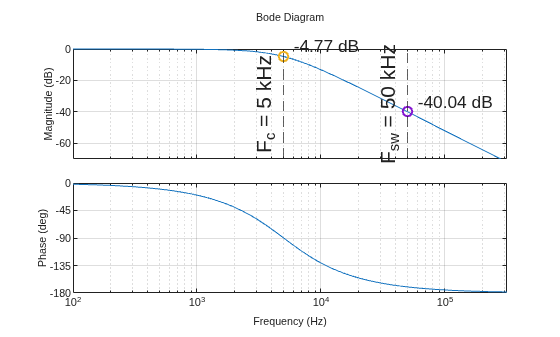


% =========================================================
% Magnitude nas frequências Fc e Fsw
% =========================================================

[mag_Fc, ~] = bode(H_tf, 2*pi*Fc_val);
[mag_Fsw, ~] = bode(H_tf, 2*pi*F_sw_val);

% Converte para dB
mag_Fc_dB  = 20*log10(squeeze(mag_Fc));
mag_Fsw_dB = 20*log10(squeeze(mag_Fsw));

% =========================================================
% Diagrama de Bode
% =========================================================

figure;

opts = bodeoptions;

% Unidades e grade
opts.FreqUnits = 'Hz';
opts.Grid = 'on';

% Cria o Bode
bodeplot(H_tf, opts);

% =========================================================
% Localiza os eixos
% =========================================================

ax = findall(gcf, 'Type', 'axes');

% Normalmente:
% ax(1) = fase
% ax(2) = magnitude

ax_mag   = ax(2);
ax_phase = ax(1);

% =========================================================
% Configurações de fonte
% =========================================================

% Cor do foreground definida no Property Editor
foreground_color = [0.851 0.851 0.851];

% ---------------------------------------------------------
% Eixo de magnitude
% ---------------------------------------------------------

% Tick labels = 12 pt
set(ax_mag, ...
    'FontSize', 12, ...
    'FontWeight', 'normal', ...
    'FontAngle', 'normal', ...
    'XColor', foreground_color, ...
    'YColor', foreground_color);

% Labels dos eixos = 13 pt
ax_mag.XLabel.FontSize = 13;
ax_mag.YLabel.FontSize = 13;

ax_mag.XLabel.FontWeight = 'normal';
ax_mag.YLabel.FontWeight = 'normal';

ax_mag.XLabel.FontAngle = 'normal';
ax_mag.YLabel.FontAngle = 'normal';

% ---------------------------------------------------------
% Eixo de fase
% ---------------------------------------------------------

% Tick labels = 12 pt
set(ax_phase, ...
    'FontSize', 12, ...
    'FontWeight', 'normal', ...
    'FontAngle', 'normal', ...
    'XColor', foreground_color, ...
    'YColor', foreground_color);

% Labels dos eixos = 13 pt
ax_phase.XLabel.FontSize = 13;
ax_phase.YLabel.FontSize = 13;

ax_phase.XLabel.FontWeight = 'normal';
ax_phase.YLabel.FontWeight = 'normal';

ax_phase.XLabel.FontAngle = 'normal';
ax_phase.YLabel.FontAngle = 'normal';

% =========================================================
% Configuração das grades
% =========================================================

ax_mag.XGrid = 'on';
ax_mag.YGrid = 'on';

ax_phase.XGrid = 'on';
ax_phase.YGrid = 'on';

% =========================================================
% Títulos = 8 pt
% =========================================================

title_mag = get(ax_mag, 'Title');
title_phase = get(ax_phase, 'Title');

title_mag.FontSize = 8;
title_phase.FontSize = 8;

title_mag.FontWeight = 'normal';
title_phase.FontWeight = 'normal';

title_mag.FontAngle = 'normal';
title_phase.FontAngle = 'normal';

% =========================================================
% Cor das grades
% =========================================================

ax_mag.GridColor = foreground_color;
ax_phase.GridColor = foreground_color;

% =========================================================
% Mantém o eixo de magnitude ativo
% =========================================================

hold(ax_mag, 'on');

% =========================================================
% Linha da frequência de corte Fc
% =========================================================

xline(ax_mag, Fc_val, '--', ...
    sprintf('F_c = %.0f kHz', Fc_val/1000), ...
    'LabelVerticalAlignment', 'middle', ...
    'LabelHorizontalAlignment', 'left', ...
    'FontSize', 16, ...
    'FontWeight', 'normal', ...
    'FontAngle', 'normal');

% =========================================================
% Linha da frequência de chaveamento Fsw
% =========================================================

xline(ax_mag, F_sw_val, '--', ...
    sprintf('F_{sw} = %.0f kHz', F_sw_val/1000), ...
    'LabelVerticalAlignment', 'middle', ...
    'LabelHorizontalAlignment', 'left', ...
    'FontSize', 16, ...
    'FontWeight', 'normal', ...
    'FontAngle', 'normal');

% =========================================================
% Marca o ponto em Fc
% =========================================================

plot(ax_mag, Fc_val, mag_Fc_dB, 'o', ...
    'MarkerSize', 7, ...
    'LineWidth', 1.5);

% =========================================================
% Marca o ponto em Fsw
% =========================================================

plot(ax_mag, F_sw_val, mag_Fsw_dB, 'o', ...
    'MarkerSize', 7, ...
    'LineWidth', 1.5);

% =========================================================
% Texto com o ganho em dB em Fc
% =========================================================

text(ax_mag, Fc_val, mag_Fc_dB, ...
    sprintf('  %.2f dB', mag_Fc_dB), ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left', ...
    'FontSize', 17, ...
    'FontWeight', 'normal', ...
    'FontAngle', 'normal');

% =========================================================
% Texto com o ganho em dB em Fsw
% =========================================================

text(ax_mag, F_sw_val, mag_Fsw_dB, ...
    sprintf('  %.2f dB', mag_Fsw_dB), ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left', ...
    'FontSize', 17, ...
    'FontWeight', 'normal', ...
    'FontAngle', 'normal');

% =========================================================
% Configuração dos textos adicionais do Bode
% I/O names = 13 pt
% =========================================================

% Procura objetos de texto associados à figura
txt = findall(gcf, 'Type', 'text');

for k = 1:length(txt)

    % Mantém títulos em 8 pt
    if txt(k) == title_mag || txt(k) == title_phase
        txt(k).FontSize = 8;

    else
        % Demais textos/I/O names
        txt(k).FontSize = 13;
        txt(k).FontWeight = 'normal';
        txt(k).FontAngle = 'normal';
    end

end

% =========================================================
% Reforça os ticks após as alterações
% =========================================================

ax_mag.FontSize   = 12;
ax_phase.FontSize = 12;

% =========================================================
% Final
% =========================================================

hold(ax_mag, 'off');